# System 1

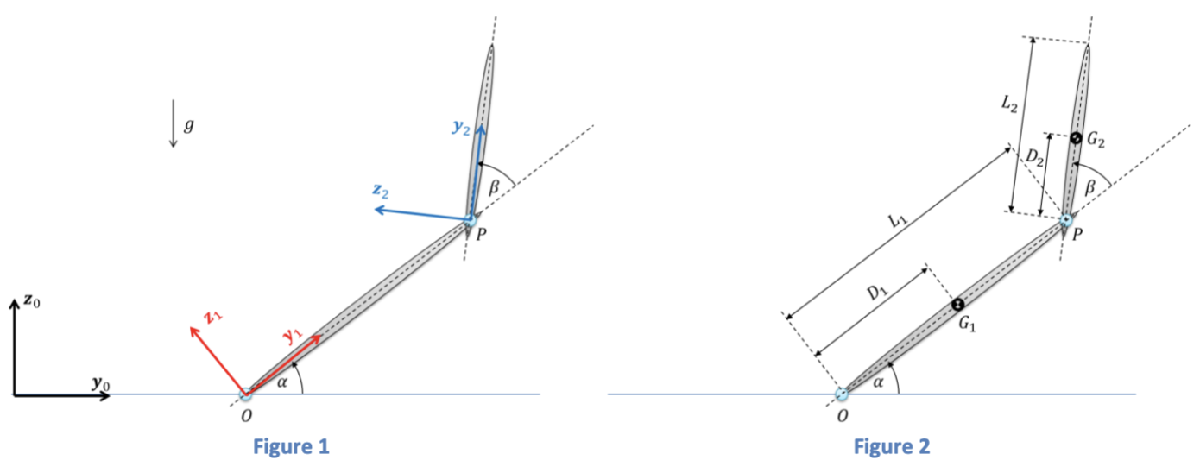

clc; clear;
% Symbolic Variables:
syms t alpha(t) beta(t)
syms D_1 D_2 L_1 L_2
syms m_1 m_2
syms I_1x I_1y I_1z I_2x I_2y I_2z

I_1_G1_1 = diag([I_1x, I_1y, I_1z]);
I_2_G2_2 = diag([I_2x, I_2y, I_2z]);



## 1) Setup Frames

R01 = [1 0 0;
       0 cos(alpha(t)) -sin(alpha(t));
       0 sin(alpha(t)) cos(alpha(t));]

$$R01 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\alpha \left(t\right)\right) & -\sin\left(\alpha \left(t\right)\right)\\ 0 & \sin\left(\alpha \left(t\right)\right) & \cos\left(\alpha \left(t\right)\right) \end{array}\right)$$

R10 = R01.'

$$R10 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\alpha \left(t\right)\right) & \sin\left(\alpha \left(t\right)\right)\\ 0 & -\sin\left(\alpha \left(t\right)\right) & \cos\left(\alpha \left(t\right)\right) \end{array}\right)$$


R12 = [1 0 0;
       0 cos(beta(t)) -sin(beta(t));
       0 sin(beta(t)) cos(beta(t));]

$$R12 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\beta \left(t\right)\right) & -\sin\left(\beta \left(t\right)\right)\\ 0 & \sin\left(\beta \left(t\right)\right) & \cos\left(\beta \left(t\right)\right) \end{array}\right)$$


R21 = R12.'

$$R21 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\beta \left(t\right)\right) & \sin\left(\beta \left(t\right)\right)\\ 0 & -\sin\left(\beta \left(t\right)\right) & \cos\left(\beta \left(t\right)\right) \end{array}\right)$$

## 2) Angular Velocities

w1_1 = [diff(alpha, t); 0; 0]

$$w1\_1(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha \left(t\right)\\ 0\\ 0 \end{array}\right)$$

w21_1 = [diff(beta, t); 0; 0]

$$w21\_1(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\beta \left(t\right)\\ 0\\ 0 \end{array}\right)$$

w2_1 = w1_1 + w21_1

$$w2\_1(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha \left(t\right)+\frac{\partial }{\partial t}\beta \left(t\right)\\ 0\\ 0 \end{array}\right)$$

w2_2 = R21*w2_1

$$w2\_2(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha \left(t\right)+\frac{\partial }{\partial t}\beta \left(t\right)\\ 0\\ 0 \end{array}\right)$$

## 3) Position Vectors

rOG1_1 = [0; D_1; 0]

$$rOG1\_1 = \left(\begin{array}{c} 0\\ D_{1}\\ 0 \end{array}\right)$$

rOP_1 = [0; L_1; 0]

$$rOP\_1 = \left(\begin{array}{c} 0\\ L_{1}\\ 0 \end{array}\right)$$

rPG2_2 = [0; D_2; 0]

$$rPG2\_2 = \left(\begin{array}{c} 0\\ D_{2}\\ 0 \end{array}\right)$$

rOG2_2 = R21*rOP_1 + rPG2_2

$$rOG2\_2 = \left(\begin{array}{c} 0\\ D_{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\\ -L_{1}\,\sin\left(\beta \left(t\right)\right) \end{array}\right)$$

## 4) Velocity and Acceleration Vectors

syms alpha_dot(t) beta_dot(t) alpha_ddot beta_ddot % not functions of time, for later

rOG1_dot_1 = diff(rOG1_1, t) + cross(w1_1, rOG1_1);
rOG2_dot_2 = diff(rOG2_2, t) + cross(w2_2, rOG2_2);

rOG1_dot_1_subs = subs(rOG1_dot_1, [diff(alpha, t), diff(beta, t)], [alpha_dot, beta_dot])
rOG2_dot_2_subs = subs(rOG2_dot_2, [diff(alpha, t), diff(beta, t)], [alpha_dot, beta_dot])

rOG1_ddot_1 = simplify(diff(rOG1_dot_1_subs, t) + cross(w1_1, rOG1_dot_1_subs));
rOG2_ddot_2 = simplify(diff(rOG2_dot_2_subs, t) + cross(w2_2, rOG2_dot_2_subs));

rOG1_ddot_1_subs = subs(rOG1_ddot_1, [diff(alpha, t), diff(beta, t), diff(alpha_dot, t), diff(beta_dot, t)], [alpha_dot, beta_dot, alpha_ddot, beta_ddot])
rOG2_ddot_2_subs = subs(rOG2_ddot_2, [diff(alpha, t), diff(beta, t), diff(alpha_dot, t), diff(beta_dot, t)], [alpha_dot, beta_dot, alpha_ddot, beta_ddot])


$$rOG1\_dot\_1\_subs(t) = \left(\begin{array}{c} 0\\ 0\\ D_{1}\,\dot{\alpha }\left(t\right) \end{array}\right)$$

$$rOG2\_dot\_2\_subs(t) = \left(\begin{array}{c} 0\\ L_{1}\,\sin\left(\beta \left(t\right)\right)\,\left(\dot{\alpha }\left(t\right)+\dot{\beta }\left(t\right)\right)-L_{1}\,\sin\left(\beta \left(t\right)\right)\,\dot{\beta }\left(t\right)\\ \left(\dot{\alpha }\left(t\right)+\dot{\beta }\left(t\right)\right)\,\left(D_{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\right)-L_{1}\,\cos\left(\beta \left(t\right)\right)\,\dot{\beta }\left(t\right) \end{array}\right)$$

$$rOG1\_ddot\_1\_subs(t) = \left(\begin{array}{c} 0\\ -D_{1}\,{\dot{\alpha }\left(t\right)}^{2}\\ D_{1}\,\ddot{\alpha } \end{array}\right)$$

$$rOG2\_ddot\_2\_subs(t) = \left(\begin{array}{c} 0\\ L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)-D_{2}\,{\dot{\beta }\left(t\right)}^{2}-L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}-2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-D_{2}\,{\dot{\alpha }\left(t\right)}^{2}\\ L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right) \end{array}\right)$$

## 5) Angular Momentum

h_G1_link1_1 = I_1_G1_1*subs(w1_1, [diff(alpha, t), diff(beta, t)], [alpha_dot, beta_dot])

$$h\_G1\_link1\_1(t) = \left(\begin{array}{c} I_{\mathrm{1x}}\,\dot{\alpha }\left(t\right)\\ 0\\ 0 \end{array}\right)$$

h_G1_link1_dot_1 = diff(h_G1_link1_1, t) + cross(w1_1, h_G1_link1_1);

h_G1_link1_dot_1_subs = subs(h_G1_link1_dot_1, [diff(alpha_dot, t), diff(beta_dot, t)], [alpha_ddot, beta_ddot])

$$h\_G1\_link1\_dot\_1\_subs(t) = \left(\begin{array}{c} I_{\mathrm{1x}}\,\ddot{\alpha }\\ 0\\ 0 \end{array}\right)$$


h_G2_link2_2 = I_2_G2_2*subs(w2_2, [diff(alpha, t), diff(beta, t)], [alpha_dot, beta_dot])

$$h\_G2\_link2\_2(t) = \left(\begin{array}{c} I_{\mathrm{2x}}\,\left(\dot{\alpha }\left(t\right)+\dot{\beta }\left(t\right)\right)\\ 0\\ 0 \end{array}\right)$$

h_G2_link2_dot_2 = diff(h_G2_link2_2, t) + cross(w2_2, h_G2_link2_2);

h_G2_link2_dot_2_subs = subs(h_G2_link2_dot_2, [diff(alpha_dot, t), diff(beta_dot, t)], [alpha_ddot, beta_ddot])

$$h\_G2\_link2\_dot\_2\_subs(t) = \left(\begin{array}{c} I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)\\ 0\\ 0 \end{array}\right)$$

## 6) FBDs

Link 1

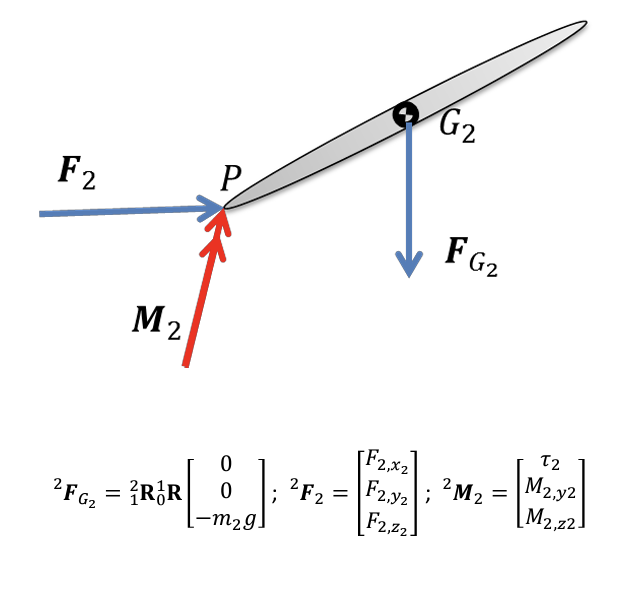

syms F2x F2y F2z tau_2 M2y M2z g
F_G_2 = R21*R10*[0; 0; -m_2*g]

$$F\_G\_2 = \left(\begin{array}{c} 0\\ -g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ -g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}\right)$$

F2_2  = [F2x; F2y; F2z]

$$F2\_2 = \left(\begin{array}{c} \mathrm{F2x}\\ \mathrm{F2y}\\ \mathrm{F2z} \end{array}\right)$$

M2_2  = [tau_2; M2y; M2z]

$$M2\_2 = \left(\begin{array}{c} \tau_{2}\\ \mathrm{M2y}\\ \mathrm{M2z} \end{array}\right)$$


% Newton-Euler Equations:
% Linear ---------
p_link2_dot_2 = m_2*rOG2_ddot_2_subs

$$p\_link2\_dot\_2(t) = \left(\begin{array}{c} 0\\ -m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)\\ m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right) \end{array}\right)$$

sum_F = F_G_2 + F2_2

$$sum\_F = \left(\begin{array}{c} \mathrm{F2x}\\ \mathrm{F2y}-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ \mathrm{F2z}-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}\right)$$


linear = p_link2_dot_2 == sum_F

$$linear(t) = \left(\begin{array}{c} 0=\mathrm{F2x}\\ -m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)=\mathrm{F2y}-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)=\mathrm{F2z}-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}\right)$$

[F2x_sol, F2y_sol, F2z_sol] = solve(linear, [F2x, F2y, F2z])

$$F2x\_sol = 0$$

$$F2y\_sol = g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)-m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)$$

$$F2z\_sol = m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)$$


F2_2 = [F2x_sol; F2y_sol; F2z_sol]

$$F2\_2 = \left(\begin{array}{c} 0\\ g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)-m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)\\ m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}\right)$$


% Angular ---------
rG2P_2 = -rPG2_2

$$rG2P\_2 = \left(\begin{array}{c} 0\\ -D_{2}\\ 0 \end{array}\right)$$

sum_M = M2_2 + cross(rG2P_2, F2_2)

$$sum\_M = \left(\begin{array}{c} \tau_{2}-D_{2}\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)\\ \mathrm{M2y}\\ \mathrm{M2z} \end{array}\right)$$


angular = h_G2_link2_dot_2_subs == sum_M

$$angular(t) = \left(\begin{array}{c} I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)=\tau_{2}-D_{2}\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)\\ 0=\mathrm{M2y}\\ 0=\mathrm{M2z} \end{array}\right)$$

[tau_2_sol, M2y_sol, M2z_sol] = solve(angular, [tau_2, M2y, M2z])

$$tau\_2\_sol = D_{2}\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)$$

$$M2y\_sol = 0$$

$$M2z\_sol = 0$$


M2_2 = [tau_2_sol; M2y_sol; M2z_sol]

$$M2\_2 = \left(\begin{array}{c} D_{2}\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)\\ 0\\ 0 \end{array}\right)$$


% First E.O.M!
eom1 = tau_2 == simplify(tau_2_sol)

$$eom1 = \tau_{2}=D_{2}\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\cos\left(\alpha \left(t\right)+\beta \left(t\right)\right)\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)$$

Link 2

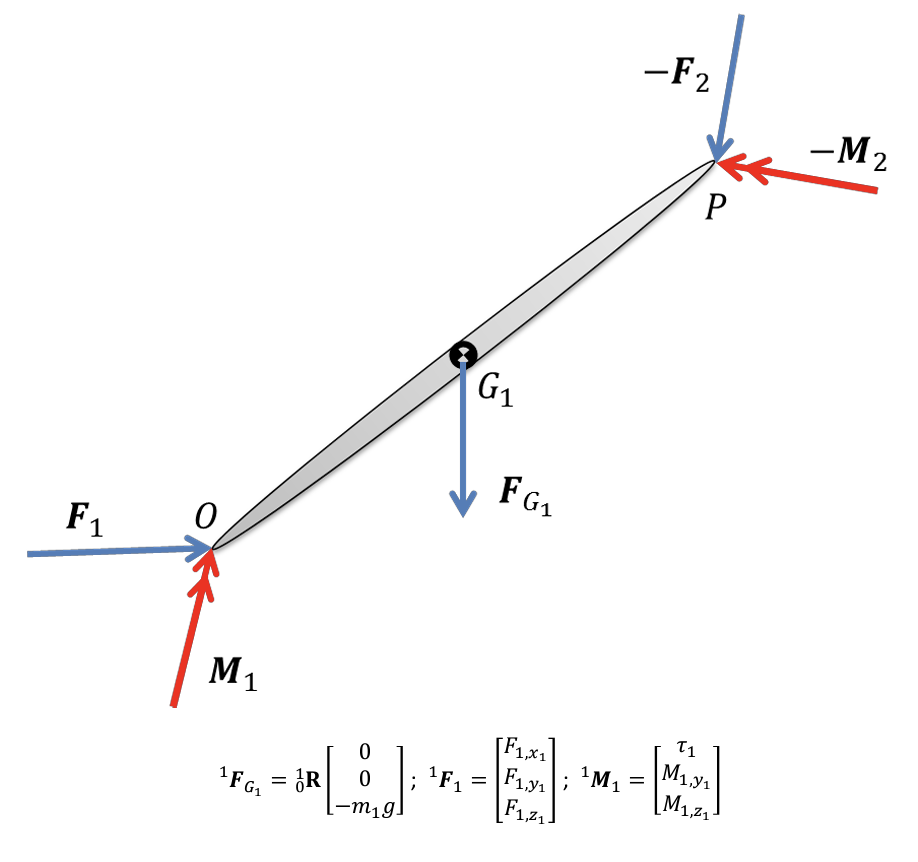

syms F1x F1y F1z tau_1 M1y M1z

F_G_1 = R10*[0; 0; -m_1*g]

$$F\_G\_1 = \left(\begin{array}{c} 0\\ -g\,m_{1}\,\sin\left(\alpha \left(t\right)\right)\\ -g\,m_{1}\,\cos\left(\alpha \left(t\right)\right) \end{array}\right)$$

F1_1  = [F1x; F1y; F1z]

$$F1\_1 = \left(\begin{array}{c} \mathrm{F1x}\\ \mathrm{F1y}\\ \mathrm{F1z} \end{array}\right)$$

M1_1  = [tau_1; M1y; M1z]

$$M1\_1 = \left(\begin{array}{c} \tau_{1}\\ \mathrm{M1y}\\ \mathrm{M1z} \end{array}\right)$$


% Newton-Euler Equations:
% Linear ---------
sumF = F_G_1 + F1_1 - R12*F2_2

$$sumF = \begin{array}{l} \left(\begin{array}{c} \mathrm{F1x}\\ \mathrm{F1y}+\sin\left(\beta \left(t\right)\right)\,\sigma_{2}+\cos\left(\beta \left(t\right)\right)\,\sigma_{1}-g\,m_{1}\,\sin\left(\alpha \left(t\right)\right)\\ \mathrm{F1z}-\cos\left(\beta \left(t\right)\right)\,\sigma_{2}+\sin\left(\beta \left(t\right)\right)\,\sigma_{1}-g\,m_{1}\,\cos\left(\alpha \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ \sigma_{2}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

p_link1_dot_1 = m_1*rOG1_ddot_1_subs

$$p\_link1\_dot\_1(t) = \left(\begin{array}{c} 0\\ -D_{1}\,m_{1}\,{\dot{\alpha }\left(t\right)}^{2}\\ D_{1}\,\ddot{\alpha }\,m_{1} \end{array}\right)$$


linear = p_link1_dot_1 == sumF

$$linear(t) = \begin{array}{l} \left(\begin{array}{c} 0=\mathrm{F1x}\\ -D_{1}\,m_{1}\,{\dot{\alpha }\left(t\right)}^{2}=\mathrm{F1y}+\sin\left(\beta \left(t\right)\right)\,\sigma_{2}+\cos\left(\beta \left(t\right)\right)\,\sigma_{1}-g\,m_{1}\,\sin\left(\alpha \left(t\right)\right)\\ D_{1}\,\ddot{\alpha }\,m_{1}=\mathrm{F1z}-\cos\left(\beta \left(t\right)\right)\,\sigma_{2}+\sin\left(\beta \left(t\right)\right)\,\sigma_{1}-g\,m_{1}\,\cos\left(\alpha \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ \sigma_{2}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$


[F1x_sol, F1y_sol, F1z_sol] = solve(linear, [F1x, F1y, F1z])

$$F1x\_sol = 0$$

$$F1y\_sol = g\,m_{1}\,\sin\left(\alpha \left(t\right)\right)-\cos\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)-D_{1}\,m_{1}\,{\dot{\alpha }\left(t\right)}^{2}-\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)$$

$$F1z\_sol = \cos\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\right)-\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}$$


F1_1 = [F1x_sol; F1y_sol; F1z_sol]

$$F1\_1 = \begin{array}{l} \left(\begin{array}{c} 0\\ g\,m_{1}\,\sin\left(\alpha \left(t\right)\right)-\cos\left(\beta \left(t\right)\right)\,\sigma_{1}-D_{1}\,m_{1}\,{\dot{\alpha }\left(t\right)}^{2}-\sin\left(\beta \left(t\right)\right)\,\sigma_{2}\\ \cos\left(\beta \left(t\right)\right)\,\sigma_{2}-\sin\left(\beta \left(t\right)\right)\,\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\\ \sigma_{2}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$


% Angular ---------
rG1O_1 = -rOG1_1;
rPG1_1 = -rOP_1 + rOG1_1;
rG1P_1 = -rPG1_1;
sum_M = M1_1 - M2_2 + cross(rG1O_1, F1_1) + cross(rG1P_1, R12*F2_2)

$$sum\_M = \begin{array}{l} \left(\begin{array}{c} \tau_{1}-D_{2}\,\sigma_{3}-\left(D_{1}-L_{1}\right)\,\left(\sigma_{2}-\sigma_{1}\right)-I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)-D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}\right)\\ \mathrm{M1y}\\ \mathrm{M1z} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$


angular = h_G1_link1_dot_1_subs == sum_M

$$angular(t) = \begin{array}{l} \left(\begin{array}{c} I_{\mathrm{1x}}\,\ddot{\alpha }=\tau_{1}-D_{2}\,\sigma_{3}-\left(D_{1}-L_{1}\right)\,\left(\sigma_{2}-\sigma_{1}\right)-I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)-D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}\right)\\ 0=\mathrm{M1y}\\ 0=\mathrm{M1z} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

[tau_1_sol, M1y_sol, M1z_sol] = solve(angular, [tau_1, M1y, M1z])

$$tau\_1\_sol = \begin{array}{l} D_{2}\,\sigma_{3}+\left(D_{1}-L_{1}\right)\,\left(\sigma_{2}-\sigma_{1}\right)+I_{\mathrm{1x}}\,\ddot{\alpha }+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)+D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

$$M1y\_sol = 0$$

$$M1z\_sol = 0$$


% Second EOM!
eom2 = tau_2 == tau_1_sol

$$eom2 = \begin{array}{l} \tau_{2}=D_{2}\,\sigma_{3}+\left(D_{1}-L_{1}\right)\,\left(\sigma_{2}-\sigma_{1}\right)+I_{\mathrm{1x}}\,\ddot{\alpha }+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)+D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right)+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$

## Isolating Equations

eqns = [eom1, eom2]

$$eqns = \begin{array}{l} \left(\begin{array}{cc} \tau_{2}=D_{2}\,\left(\sigma_{4}+g\,m_{2}\,\cos\left(\alpha \left(t\right)+\beta \left(t\right)\right)\right)+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right) & \tau_{2}=D_{2}\,\sigma_{3}+\left(D_{1}-L_{1}\right)\,\left(\sigma_{2}-\sigma_{1}\right)+I_{\mathrm{1x}}\,\ddot{\alpha }+I_{\mathrm{2x}}\,\left(\ddot{\alpha }+\ddot{\beta }\right)+D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)+D_{1}\,\ddot{\alpha }\,m_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)-L_{1}\,\ddot{\alpha }\,\sin\left(\beta \left(t\right)\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=\sigma_{4}+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right)\\ \sigma_{4}=m_{2}\,\left(L_{1}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,\ddot{\alpha }+D_{2}\,\ddot{\beta }+L_{1}\,\ddot{\alpha }\,\cos\left(\beta \left(t\right)\right)\right) \end{array}$$

[A,b]=equationsToMatrix(eqns,[alpha_ddot, beta_ddot])

$$A = \begin{array}{l} \left(\begin{array}{cc} -I_{\mathrm{2x}}-D_{2}\,m_{2}\,\sigma_{3} & -m_{2}\,{D_{2}}^{2}-I_{\mathrm{2x}}\\ -I_{\mathrm{1x}}-I_{\mathrm{2x}}-\left(D_{1}-L_{1}\right)\,\left(\sigma_{1}+\sigma_{2}\right)-D_{1}\,\left(\sigma_{1}+D_{1}\,m_{1}+\sigma_{2}\right)-D_{2}\,m_{2}\,\sigma_{3} & -I_{\mathrm{2x}}-{D_{2}}^{2}\,m_{2}-D_{1}\,D_{2}\,m_{2}\,\cos\left(\beta \left(t\right)\right)-D_{2}\,m_{2}\,\cos\left(\beta \left(t\right)\right)\,\left(D_{1}-L_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,m_{2}\,{\sin\left(\beta \left(t\right)\right)}^{2}\\ \sigma_{2}=m_{2}\,\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=D_{2}+L_{1}\,\cos\left(\beta \left(t\right)\right) \end{array}$$

$$b = \begin{array}{l} \left(\begin{array}{c} D_{2}\,\left(L_{1}\,m_{2}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+g\,m_{2}\,\cos\left(\alpha \left(t\right)+\beta \left(t\right)\right)\right)-\tau_{2}\\ D_{1}\,\left(\sigma_{2}-\sigma_{1}+g\,m_{1}\,\cos\left(\alpha \left(t\right)\right)\right)-\tau_{2}-\left(D_{1}-L_{1}\right)\,\left(\sigma_{1}-\sigma_{2}\right)+D_{2}\,\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta \left(t\right)\right)\,\left(m_{2}\,\left(D_{2}\,{\dot{\alpha }\left(t\right)}^{2}+D_{2}\,{\dot{\beta }\left(t\right)}^{2}+L_{1}\,\cos\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+2\,D_{2}\,\dot{\alpha }\left(t\right)\,\dot{\beta }\left(t\right)\right)-g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+\cos\left(\beta \left(t\right)\right)\,\sin\left(\alpha \left(t\right)\right)\right)\right)\\ \sigma_{2}=\cos\left(\beta \left(t\right)\right)\,\sigma_{3}\\ \sigma_{3}=L_{1}\,m_{2}\,\sin\left(\beta \left(t\right)\right)\,{\dot{\alpha }\left(t\right)}^{2}+g\,m_{2}\,\left(\cos\left(\alpha \left(t\right)\right)\,\cos\left(\beta \left(t\right)\right)-\sin\left(\alpha \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\right) \end{array}$$


X = A\b